# Motion Planning with RRT for a Robot Manipulator

Plan a grasping motion for a **Kinova Jaco Assistive Robotics Arm** using the rapidly-exploring random tree (RRT) algorithm. This example uses a `plannerRRTStar` object to sample states and plan the robot motion. Provided example helpers illustrate how to define custom state spaces and state validation for motion planning applications.

Load a Kinova Jaco model from the robot library. This particular model includes the three-finger gripper.

clc
clear 
close all

kin = loadrobot('kinovaJacoJ2S7S300');
num_of_env = 1;
num_of_itr_per_combo = 2;
num_of_planner = 1;
time_to_execute = zeros(num_of_env, num_of_planner);
visualize = 0;
execution_time = zeros(num_of_env, num_of_planner, num_of_itr_per_combo);
for a = 1:1:num_of_env
    env = a;
    for b = 1:1:num_of_planner
        average_time = 0;
        for c = 1:1:num_of_itr_per_combo
            tic;
            fprintf('Number of iterations: %f.\n',c)
            plannerdec = b;
            

Number of iterations: 1.000000.


## Create The Environment

Using collision object primitives, add a floor, two table tops, and a cylinder can. Specify the size and pose of these objects. The provided image shows the environment created.

            if env == 1
            disp('Environment 1')
            floor = collisionBox(1, 1, 0.01);
            tabletop1 = collisionBox(0.4,1,0.02);
            tabletop1.Pose = trvec2tform([0.3,0,0.6]);
            tabletop2 = collisionBox(0.6,0.2,0.02);
            tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
            can = collisionCylinder(0.03,0.16);
            can.Pose = trvec2tform([0.3,0.0,0.7]);
            worldCollisionArray = {floor tabletop1 tabletop2 can};
    
    
            elseif env == 2
            disp('Environment 2')
            floor = collisionBox(1, 1, 0.01);
            tabletop1 = collisionBox(0.4,1,0.02);
            tabletop1.Pose = trvec2tform([0.3,0,0.6]);
            tabletop2 = collisionBox(0.6,0.2,0.02);
            tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
            can = collisionCylinder(0.03,0.16);
            can.Pose = trvec2tform([0.3,0.0,0.7]);
            can1 = collisionCylinder(0.03,0.16);
            can1.Pose = trvec2tform([0.5,0.2,0.7]);
            can2 = collisionBox(0.03,0.2,0.16);
            can2.Pose = trvec2tform([0.15,0.0,0.7]);
            worldCollisionArray = {floor tabletop1 tabletop2 can can1 can2};
    
        
            elseif env == 3
            disp('Environment 3')
            floor = collisionBox(1, 1, 0.01);
            tabletop1 = collisionBox(0.4,1,0.02);
            tabletop1.Pose = trvec2tform([0.3,0,0.6]);
            tabletop2 = collisionBox(0.6,0.2,0.02);
            tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
            can = collisionCylinder(0.03,0.16);
            can.Pose = trvec2tform([0.3,0.0,0.7]);
            can1 = collisionCylinder(0.03,0.16);
            can1.Pose = trvec2tform([0.5,0.2,0.7]);
            can2 = collisionBox(0.03,0.2,0.16);
            can2.Pose = trvec2tform([0.15,0.0,0.7]);
            end

Environment 1



            exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

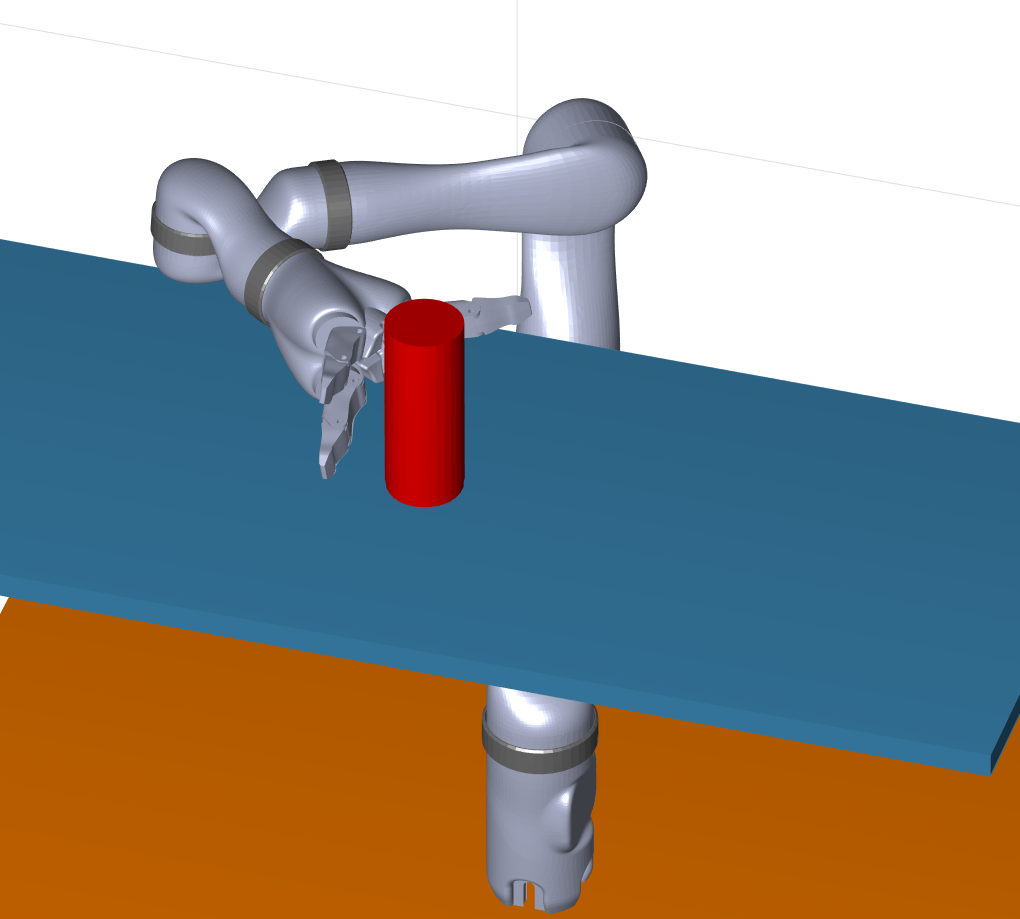

## Customize The State Space For Manipulator

The Kinova arm has ten degrees of freedom (DoFs), with the last three DoFs corresponding to the fingers. Only use the first seven DoFs for the planning and keep the fingers at zero configuration (open wide). An `ExampleHelperRigidBodyTreeStateSpace` state space is created to represent the configuration space (joint space). `ExampleHelperRigidBodyTreeStateSpace` samples feasible states for the robot arm. The `sampleUniform` function of the state space alternates between the following two sampling strategies with equal probability:   

- Uniformly random sample the end effector pose in the **Workspace Goal Region** around the reference goal pose, then map it to the joint space through inverse kinematics. Joint limits are respected.

- Uniformly random sample in the joint space. Joint limits are respected.

The first sampling strategy helps guide the RRT planner towards the goal region in the task space so that RRT can converge to a solution faster instead of getting lost in the seven DoF joint space.

Using **Workspace Goal Region** (WGR) instead of single goal pose increases the chance of finding a solution by biasing samples to the goal region. WGR defines a continuum of acceptable end-effector poses for certain tasks. For example, the robot can approach from multiple directions to grasp a cup of water from the side, as long as it doesn't collide with the environment. The concept of WGR is first proposed by Dmitry Berenson et al [1] in 2009. This algorithm later evolved into **Task Space Regions **[2]. A WGR consists of three parts:

- `Twgr_0` - The reference transform of a WGR in world ({0}) coordinates

- `Te_w` - The end-effector offset transform in the {w} coordinates, {w} is sampled from WGR

- `Bounds` - A 6-by-2 matrix of bounds in the WGR reference coordinates. The first three rows of `Bounds` set the allowable translation along the x, y, and z axes (in meters) respectively and the last three set the allowable rotations about the allowable rotations about the x, y, and z axes (in radians). Note that the Roll-Pitch-Yaw (RPY) Euler angles are used as they can be intuitively specified.

 You can define and concatenate multiple WGRs in one planning problem. In this example, only one WGR is allowed.

            % Create state space and set workspace goal regions (WGRs)
            ss = ExampleHelperRigidBodyTreeStateSpace(kin);
            ss.EndEffector = 'j2s7s300_end_effector';
            
            % Define the workspace goal region (WGR)
            % This WGR tells the planner that the can shall be grasped from
            % the side and the actual grasp height may wiggle at most 1 cm.
            
            % This is the orientation offset between the end-effector in grasping pose and the can frame
            R = [0 0 1; 1 0 0; 0 1 0]; 
            
            Tw_0 = can.Pose;
            Te_w = rotm2tform(R);
            bounds = [0 0;       % x
                      0 0;       % y
                      0 0.01;    % z
                      0 0;       % R
                      0 0;       % P
                     -pi pi];    % Y
            setWorkspaceGoalRegion(ss,Tw_0,Te_w,bounds);


## Customize The State Validator

The customized state validator, `ExampleHelperValidatorRigidBodyTree`, provides rigid body collision checking between the robot and the environment. This validator checks sampled configurations and the planner should discard invalid states.

            sv = ExampleHelperValidatorRigidBodyTree(ss);
            
            % Add obstacles in the environment
            addFixedObstacle(sv,tabletop1, 'tabletop1', [71 161 214]/256);
            addFixedObstacle(sv,tabletop2, 'tabletop2', [71 161 214]/256);
            addFixedObstacle(sv,can, 'can', 'r');
            addFixedObstacle(sv,floor, 'floor', [1,0.5,0]);
            if env == 2
            addFixedObstacle(sv,can1, 'can1', 'r');
            addFixedObstacle(sv,can2, 'can2', 'r');
            end
            % Skip collision checking for certain bodies for performance
            skipCollisionCheck(sv,'root'); % root will never touch any obstacles
            skipCollisionCheck(sv,'j2s7s300_link_base'); % base will never touch any obstacles
            skipCollisionCheck(sv,'j2s7s300_end_effector'); % this is a virtual frame
            
            % Set the validation distance
            sv.ValidationDistance = 0.01;

## Plan The Grasp Motion

Use the `plannerRRT` object with the customized state space and state validator objects. Specify the start and goal configurations by using `inverseKinematics` to solve for configrations based on the end-effector pose.  Specify the `GoalReachedFcn` using `exampleHelperIsStateInWorkspaceGoalRegion`, which checks if a path reaches the goal region.

            % Set random seeds for repeatable results
            rng(0,'twister') % 0
            
            % Compute the reference goal configuration. Note this is applicable only when goal bias is larger than 0. 
            Te_0ref = Tw_0*Te_w; % Reference end-effector pose in world coordinates, derived from WGR
            ik = inverseKinematics('RigidBodyTree',kin);
            refGoalConfig = ik(ss.EndEffector,Te_0ref,ones(1,6),homeConfiguration(ss.RigidBodyTree));
            
            % Compute the initial configuration (end-effector is initially under the table)
            T = Te_0ref;
            T(1,4) = 0.3;
            T(2,4) = 0.0;
            T(3,4) = 0.4;
            initConfig = ik(ss.EndEffector,T,ones(1,6),homeConfiguration(ss.RigidBodyTree));
            
            
            % Create the planner from previously created state space and state validator
            if plannerdec == 1
                planner = plannerRRT(ss,sv);
                disp('RRT planner')
            elseif plannerdec == 2
                planner = plannerRRTstar(ss,sv);
                disp('RRT* planner')
            elseif plannerdec == 3
                planner = plannerHybridAStar(sv);
                disp('Hybrid A* planner')
            end
            % If a node in the tree falls in the WGR, a path is considered found.
            planner.GoalReachedFcn = @exampleHelperIsStateInWorkspaceGoalRegion;
            
            % Set the max connection distance.
            planner.MaxConnectionDistance = 0.5;
            
            % With WGR, there is no need to specify a particular goal configuration (use
            % initConfig to hold the place).
            % As a result, one can set GoalBias to zero.
            planner.GoalBias = 0;
            [pthObj,solnInfo] = plan(planner,initConfig, initConfig);

## Visualize The Grasp Motion

The found path is first smoothed through a recursive corner-cutting strategy [3], before the motion is animated.

%             % Smooth the path.
             interpolate(pthObj,100);
             newPathObj = exampleHelperPathSmoothing(pthObj,sv);
             interpolate(newPathObj,200);
%             
%             figure
             states = newPathObj.States;
%             
%             % Draw the robot.
             ax = show(kin,states(1,:));
            zlim(ax, [-0.03, 1.4])
            xlim(ax, [-1, 1])
            ylim(ax, [-1, 1])
%             
%             
%             % Render the environment.
            hold on
            showObstacles(sv, ax);
            view(146, 33)
            camzoom(1.5)
           
%             % Show the motion.
            if visualize == 1
                for i = 2:length(states)
                    show(kin,states(i,:),'PreservePlot',false,'Frames','off','Parent',ax);
                    drawnow
                end
            else
                i = length(states);
            end
             q = states(i,:);
%             
%             % Grab the can.
             q = exampleHelperEndEffectorGrab(sv,'can',q, ax);

Set a target psotion for the can on the other tabletop.

            targetPos = [-0.15,0.35,0.51];
            exampleHelperDrawHorizontalCircle(targetPos,0.02,'y',ax);

## Plan The Move Motion

During the move motion, keep the cylinder can level at all time to avoid spill. Specify an additional constraint on the interim manipulator configurations for the RRT planner. Turn the constraint on by setting the `UseConstrainedSampling` property to true.

            Tw_0 = trvec2tform(targetPos+[0,0,0.08]); 
            Te_w = rotm2tform(R);
            bounds =  [0 0;       % x
                       0 0;       % y
                       0 0;       % z
                       0 0;       % R
                       0 0;       % P
                      -pi pi];    % Y
            setWorkspaceGoalRegion(ss,Tw_0,Te_w,bounds);
            ss.UseConstrainedSampling = true;
            planner.MaxConnectionDistance = 0.05;
            [pthObj2,~] = plan(planner,q,q);

Visualize the motion.

            states = pthObj2.States;
%             
            view(ax, 152,45)
            if visualize == 1
                for i = 2:length(states)
                    show(kin,states(i,:),'PreservePlot',false,'Frames','off','Parent',ax);
                    drawnow
                end
            else
                i = length(states);
            end
            q = states(i,:);
%             
%             % let go of the can
%%%%%%%%%  Cannot do realise of object since we are doing it offscreen %%%%%%
            q = exampleHelperEndEffectorRelease(sv,q,ax);
            average_time = average_time + toc;
            execution_time(a,b,c) = average_time;
            close all
        end
        
        time_to_execute(a, b) = average_time/num_of_itr_per_combo;
    end
end
save('Test_2_env-1_planner-1_avg-2_without-display', 'time_to_execute')
save('Test_2_execution-time_env-1_planner-1_without-display', 'execution_time')

## References

[1] D. Berenson, S. Srinivasa, D. Ferguson, A. Collet, and J. Kuffner, "Manipulation Planning with Workspace Goal Regions", in *Proceedings of IEEE International Conference on Robotics and Automation, *2009, pp.1397-1403

[2] D. Berenson, S. Srinivasa, and J. Kuffner, "Task Space Regions: A Framework for Pose-Constrained Manipulation Planning", *International Journal of Robotics Research*, Vol. 30, No. 12 (2011): 1435-1460

[3] P. Chen, and Y. Hwang, "SANDROS: A Dynamic Graph Search Algorithm for Motion Planning", IEEE Transaction on Robotics and Automation, Vol. 14 No. 3 (1998): 390-403

*Copyright 2019-2020 The MathWorks, Inc.*